clear
clc

%%%%%%%%%%%%%%
%%% 物理量 %%%
%%%%%%%%%%%%%%

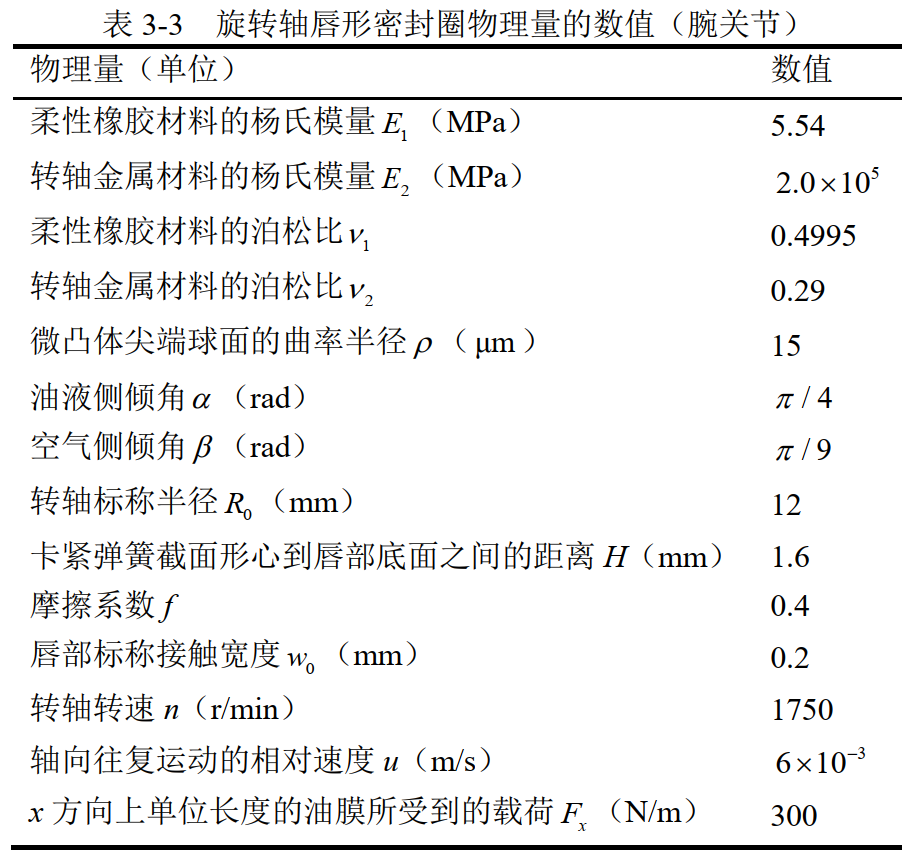

delta_interf = 6.270583249144252e-04; % 过盈量(m) 使用该过盈量估计微凸体数量

rou = 15e-6; % 微凸体尖端球面的曲率半径(m)%待修改
E1 = 5.54e6; % 柔性橡胶材料的杨氏模量(Pa)
E2 = 2e11; % 转轴金属材料的杨氏模量(Pa)
v1 = 0.4995; % 柔性橡胶材料的泊松比
v2 = 0.29; % 转轴金属材料的泊松比

alpha = pi/4; % 油液侧倾角(rad)
beta = pi/9; % 空气侧倾角(rad)
R0 = 12e-3; % 转轴标称半径(m)
H = 1.6e-3; % 卡紧弹簧截面形心到唇部底面之间的距离(m)
f = 0.4; % 摩擦系数
w0 = 0.2e-3; % 唇部标称接触宽度(m)
I = 80; % 谐波减速器减速比
n = 1750; % 电机转速(r/min)
u = 6e-3; % 轴向往复运动的相对速度(m/s)
p_oil = 10e6; % 油液压力(Pa)
mu0 = 71.3e-3; % 液压油的额定动力黏度(Pa·s)
alpha_mu = 1/(9.43e7+2.8e-1*p_oil); % 黏性压力系数(1/Pa)

mu = mu0*exp(alpha_mu*p_oil); % 实际动力黏度(Pa·s) 
R = R0 + delta_interf/2; % 考虑过盈量后的实际转轴半径(m)
E = 1/((1-v1^2)/E1+(1-v2^2)/E2); % 综合杨氏模量(Pa)

F = sqrt(2)*rou^(1/2)*E*delta_interf^(3/2)/3; % 单位微凸体产生的径向力(N)
p_contact = 2*sqrt(2)*rou^(-1/2)*E*delta_interf^(1/2)/(3*pi); % 接触压强(Pa)
A = F/p_contact; % 单位微凸体产生的接触面积(m2)

Sc = 2*pi*R*w0; % 有效接触面积(m^2)
N = Sc/A;
F_sum = N*F;
h_delta = F_sum*H/(1.33*Sc*E1/2); % 径向变形量(m)                                               修改1: F_sum 替换 F
w = w0 + (tan(alpha)+tan(beta))*h_delta/(tan(alpha)*tan(beta)); % 唇部实际接触宽度(m)
Fx = 300; % 单位长度的轴向载荷(N/m)                                                              修改2: 假定Fx为常数

h = (mu*u*tan(beta)/(Fx*(tan(alpha)+tan(beta))))^(1/2)*w; % 油膜厚度(m)

p_contact = 2*sqrt(2)*rou^(-1/2)*E*delta_interf^(1/2)/(3*pi); % 接触压强(Pa)
                                                                                               % 修改4: 添加N
q1 = abs(-tan(beta)^(1/2)*(tan(alpha)-tan(beta))*pi*mu^(1/2)*u^(3/2)*(2*R0+delta_interf)*(w0+2*sqrt(2)*(tan(alpha)+tan(beta))*rou^(1/2)*N*E*H*delta_interf^(3/2)/(3*1.33*pi*tan(alpha)*tan(beta)*(2*R0+delta_interf)*w0*E1))/(tan(alpha)*(tan(alpha)+tan(beta))^(1/2)*6*Fx^(1/2)));
Q = N*sqrt(2)*pi^2*rou^(1/2)*f*n*E*(2*R0+delta_interf)*delta_interf^(3/2)/180; % 摩擦生热量 (W) % 修改5: 添加N

%%%%%%%%%%%%
%%% 作图 %%%
%%%%%%%%%%%%

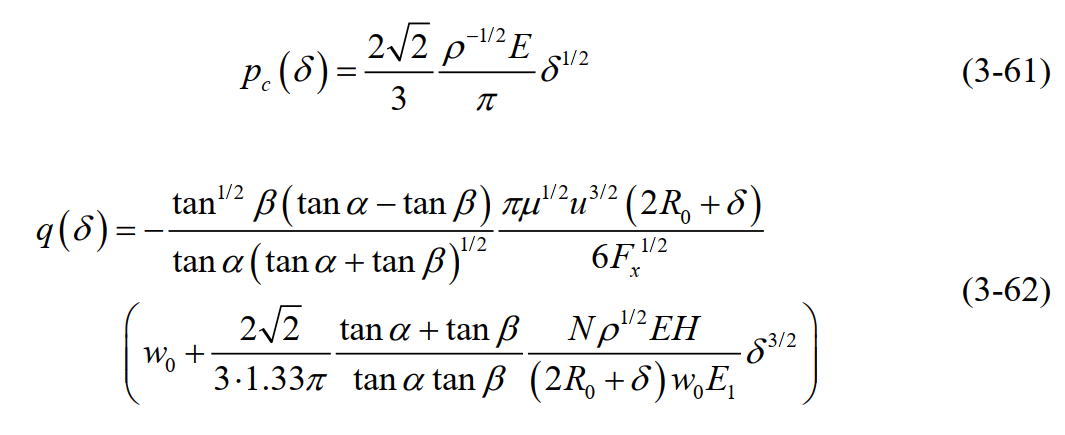

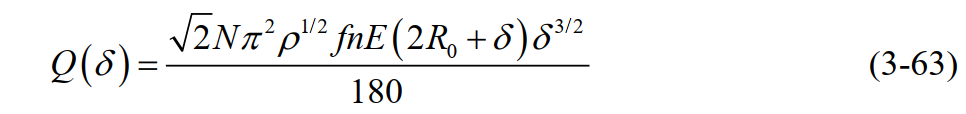

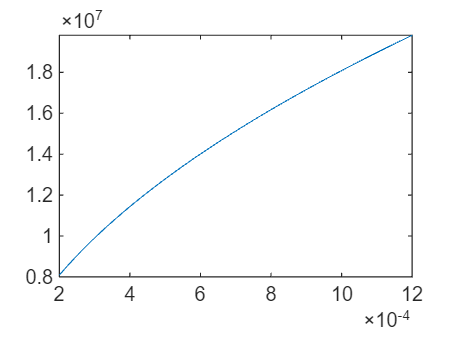

f_p_contact = @(delta_interf) 2*sqrt(2)*rou^(-1/2)*E*delta_interf^(1/2)/(3*pi);
f_q1 = @(delta_interf) abs(-tan(beta)^(1/2)*(tan(alpha)-tan(beta))*pi*mu^(1/2)*u^(3/2)*(2*R0+delta_interf)*(w0+2*sqrt(2)*(tan(alpha)+tan(beta))*rou^(1/2)*N*E*H*delta_interf^(3/2)/(3*1.33*pi*tan(alpha)*tan(beta)*(2*R0+delta_interf)*w0*E1))/(tan(alpha)*(tan(alpha)+tan(beta))^(1/2)*6*Fx^(1/2)));
f_Q = @(delta_interf) N*sqrt(2)*pi^2*rou^(1/2)*f*n*E*(2*R0+delta_interf)*delta_interf^(3/2)/180;

fplot(f_p_contact,[0.2e-3, 1.2e-3]);

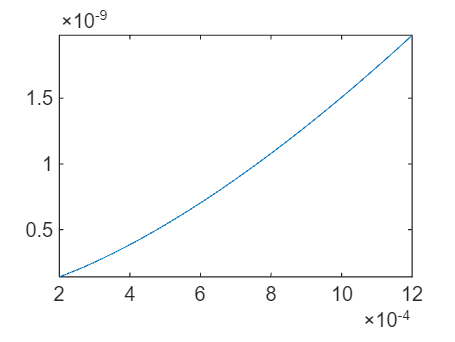

fplot(f_q1,[0.2e-3, 1.2e-3]);

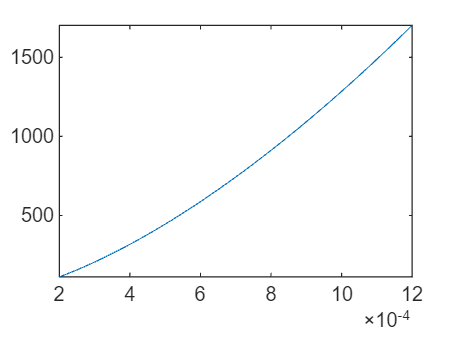

fplot(f_Q,[0.2e-3, 1.2e-3]);

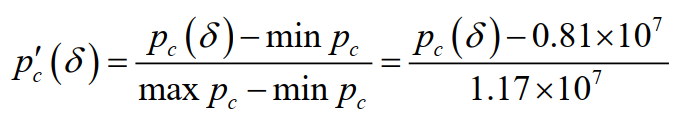

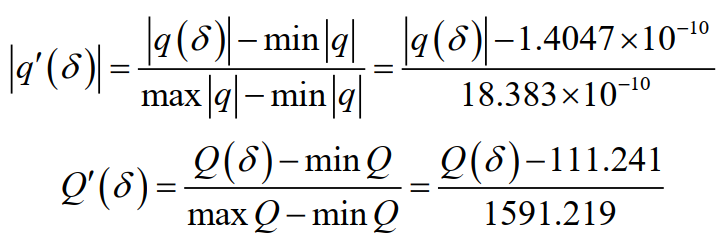

f_p_contact_normal = @(delta_interf) (2*sqrt(2)*rou^(-1/2)*E*delta_interf^(1/2)/(3*pi) - 0.81e7)/1.17e7;                                                                                           
f_q_normal = @(delta_interf) -(abs(-tan(beta)^(1/2)*(tan(alpha)-tan(beta))*pi*mu^(1/2)*u^(3/2)*(2*R0+delta_interf)*(w0+2*sqrt(2)*(tan(alpha)+tan(beta))*rou^(1/2)*N*E*H*delta_interf^(3/2)/(3*1.33*pi*tan(alpha)*tan(beta)*(2*R0+delta_interf)*w0*E1))/(tan(alpha)*(tan(alpha)+tan(beta))^(1/2)*6*Fx^(1/2))) - 1.4047e-10)/18.383e-10;% 绝对值
f_Q_normal = @(delta_interf) (N*sqrt(2)*pi^2*rou^(1/2)*f*n*E*(2*R0+delta_interf)*delta_interf^(3/2)/180 - 111.241)/1591.219;

将 N 视为 delta_interf 的因变量

% N = @(delta_interf)(2*pi*(R0 + delta_interf/2)*w0)/((sqrt(2)*rou^(1/2)*E*delta_interf^(3/2)/3)/(2*sqrt(2)*rou^(-1/2)*E*delta_interf^(1/2)/(3*pi)));
% fplot(N,[0.2e-3, 1.2e-3]);
% 
% f_q1 = @(delta_interf) tan(beta)^(1/2)*(tan(alpha)-tan(beta))*pi*mu^(1/2)*u^(3/2)*(2*R0+delta_interf)*(w0+2*sqrt(2)*(tan(alpha)+tan(beta))*rou^(1/2)*(2*pi*(R0 + delta_interf/2)*w0)/((sqrt(2)*rou^(1/2)*E*delta_interf^(3/2)/3)/(2*sqrt(2)*rou^(-1/2)*E*delta_interf^(1/2)/(3*pi)))*E*H*delta_interf^(3/2)/(3*1.33*pi*tan(alpha)*tan(beta)*(2*R0+delta_interf)*w0*E1))/(tan(alpha)*(tan(alpha)+tan(beta))^(1/2)*6*Fx^(1/2));
% fplot(f_q1,[0.2e-3, 1.2e-3]);

fplot(f_p_contact_normal,[0.2e-3, 1.2e-3]);

hold on
fplot(f_q_normal,[0.2e-3, 1.2e-3]);

fplot(f_Q_normal,[0.2e-3, 1.2e-3]);

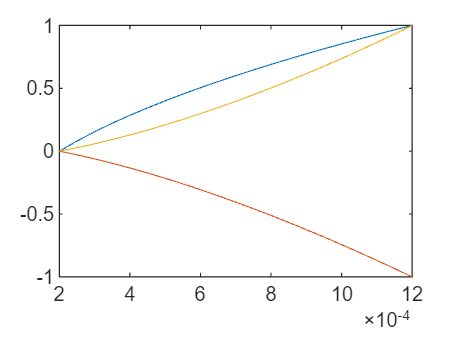

hold off


%%%%%%%%%%%%%%
%%% 归一化 %%%
%%%%%%%%%%%%%%

delta_interf = optimvar('delta_interf','LowerBound',0.2e-3,'UpperBound',1.2e-3);
f_p_contact = 2*sqrt(2)*rou^(-1/2)*E*delta_interf^(1/2)/(3*pi);
f_p_contact_normal = (f_p_contact - 0.81e7)/1.17e7;

f_q = tan(beta)^(1/2)*(tan(alpha)-tan(beta))*pi*mu^(1/2)*u^(3/2)*(2*R0+delta_interf)*(w0+2*sqrt(2)*(tan(alpha)+tan(beta))*rou^(1/2)*N*E*H*delta_interf^(3/2)/(3*1.33*pi*tan(alpha)*tan(beta)*(2*R0+delta_interf)*w0*E1))/(tan(alpha)*(tan(alpha)+tan(beta))^(1/2)*6*Fx^(1/2));
f_q_normal = (f_q - 1.4047e-10)/18.383e-10;% 绝对值                                             % 修改6: 修改归一化值

f_Q = N*sqrt(2)*pi^2*rou^(1/2)*f*n*E*(2*R0+delta_interf)*delta_interf^(3/2)/180;                % 修改7: 添加N
f_Q_normal = (f_Q - 111.241)/1591.219;                                                          % 修改8: 修改归一化值

%%%%%%%%%%%%%%%%%
%%% 多目标优化 %%%
%%%%%%%%%%%%%%%%%

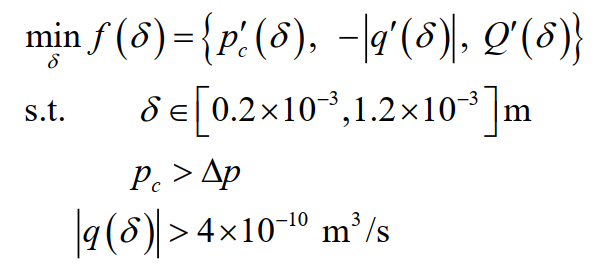

prob = optimproblem;
prob.Objective.first = f_p_contact_normal;
prob.Objective.second = -f_q_normal;
prob.Objective.third = f_Q_normal;

cons1 = f_p_contact >= 0.1967e5;
cons2 = f_q >= 4e-10;                                                                          % 修改9: 下限值
prob.Constraints.cons1 = cons1;
prob.Constraints.cons1 = cons2;

options = optimoptions('gamultiobj','FunctionTolerance',1e-6);
% rng default % For reproducibility
sol = solve(prob,'Options',options);

将使用 gamultiobj 求解问题。
gamultiobj stopped because it exceeded options.MaxGenerations.


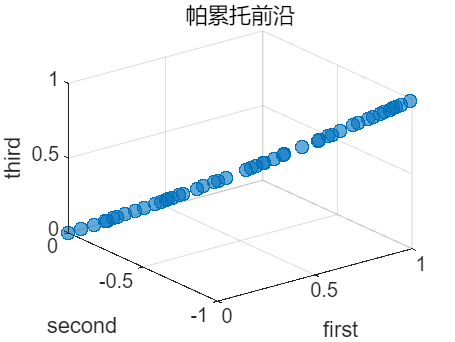

paretoplot(sol);